# Metody optymalizacji - ćwiczenie 3

# Zadanie 1

### Nina Łabęcka 311339 grupa czwartek 14:15

### Dominika Pacek 311378 grupa czwartek 18:15

clc
clear
cvx_clear

Wczytanie danych

dane = load("zadanie1\Data01.mat")

dane = struct with fields:
    t: [1001×1 double]
    y: [1001×1 double]


y = dane.y;
n = length(y);
m = length(y) - 1;

Rozwiązanie (7) metodą programowania liniowego

q = 1.7

q = 1.7000

D = zeros(m, n);
for i = 1:m
    D(i, i) = -1;
    D(i, i+1) = 1;
end

D =     -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0    -1     1     0     0     0     0     0     0     0     0     0     0   


A = [
        eye(n), -eye(n), zeros(n,m);           
        -eye(n), -eye(n), zeros(n,m);          
        zeros(1,n), zeros(1,n), ones(1,m);     
        -D, zeros(m,n), -eye(m);               
        D, zeros(m,n), -eye(m)                 
    ];

c = [
        zeros(n,1);
        ones(n, 1);
        zeros(m,1)
    ];

b = [
        y;
        -y
        q;
        zeros(m,1);
        zeros(m,1)
    ];

x = linprog(c, A, b);

Optimal solution found.



v1 = x(1:n);

Rozwiązanie (8) metodą programowania liniowego

tau = 4

tau = 4

xi = optimvar('xi', n, 1);
delta = optimvar('delta', m, 1);
v_lp = optimvar('v_lp', n, 1);

p = optimproblem('ObjectiveSense', 'min');
p.Objective = sum(xi) + sum(delta) * tau;
p.Constraints.c1 = y - v_lp >= -xi;
p.Constraints.c2 = y - v_lp <= xi;

p.Constraints.c3 = v_lp(2:end)-v_lp(1:end-1) >= -delta;
p.Constraints.c4 = v_lp(2:end)-v_lp(1:end-1) <= delta;

options = optimoptions('linprog','Algorithm','dual-simplex','OptimalityTolerance',1e-10);
sol = solve(p,'Options',options);

Solving problem using linprog.

Optimal solution found.



v2 = sol.v_lp;

Rysowanie wykresu

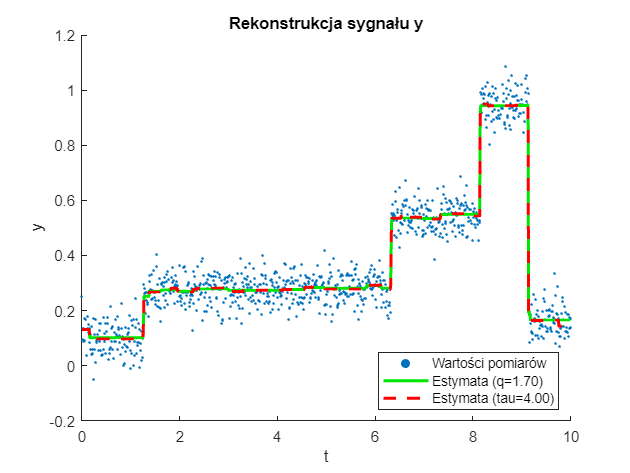

fig = figure;
    scatter(dane.t, dane.y, 3, 'filled', 'DisplayName', 'Wartości pomiarów');
    hold on;
    plot(dane.t, v1, 'LineWidth', 2, 'Color', [0, 0.9, 0], ...
        'DisplayName', sprintf('Estymata (q=%.2f)', q));
    plot(dane.t, v2, 'LineWidth', 2, 'LineStyle', '--', 'Color', 'red', ...
        'DisplayName', sprintf('Estymata (tau=%.2f)', tau))
    xlabel('t');
    ylabel('y');
    legend('Location', 'southeast');
    title('Rekonstrukcja sygnału y');